# SNW_VFI_PARAM Base Solution Analysis

This is the example vignette for function: snw_vfi_main_bisec_vec from the [**PrjOptiSNW Package**](https://fanwangecon.github.io/PrjOptiSNW/)**. **This function solves for policy function with vectorized bisection. Base Solution Analysis.

## Test SNW_VFI_MAIN_BISEC_VEC Defaults Base (Medium)

Call the function with defaults.

mp_param = snw_mp_param('default_base');
[V_VFI,ap_VFI,cons_VFI,exitflag_VFI] = snw_vfi_main_bisec_vec(mp_param);

SNW_VFI_MAIN: Finished Age Group:42 of 42
SNW_VFI_MAIN: Finished Age Group:41 of 42
SNW_VFI_MAIN: Finished Age Group:40 of 42
SNW_VFI_MAIN: Finished Age Group:39 of 42
SNW_VFI_MAIN: Finished Age Group:38 of 42
SNW_VFI_MAIN: Finished Age Group:37 of 42
SNW_VFI_MAIN: Finished Age Group:36 of 42
SNW_VFI_MAIN: Finished Age Group:35 of 42
SNW_VFI_MAIN: Finished Age Group:34 of 42
SNW_VFI_MAIN: Finished Age Group:33 of 42
SNW_VFI_MAIN: Finished Age Group:32 of 42
SNW_VFI_MAIN: Finished Age Group:31 of 42
SNW_VFI_MAIN: Finished Age Group:30 of 42
SNW_VFI_MAIN: Finished Age Group:29 of 42
SNW_VFI_MAIN: Finished Age Group:28 of 42
SNW_VFI_MAIN: Finished Age Group:27 of 42
SNW_VFI_MAIN: Finished Age Group:26 of 42
SNW_VFI_MAIN: Finished Age Group:25 of 42
SNW_VFI_MAIN: Finished Age Group:24 of 42
SNW_VFI_MAIN: Finished Age Group:23 of 42
SNW_VFI_MAIN: Finished Age Group:22 of 42
SNW_VFI_MAIN: Finished Age Group:21 of 42
SNW_VFI_MAIN: Finished Age Group:20 of 42
SNW_VFI_MAIN: Finished Age Group:1

## Base Param Results Define Frames

Define the matrix dimensions names and dimension vector values. Policy and Value Functions share the same ND dimensional structure.

% Grids:
age_grid = [19, 21:2:99, 100];
agrid = mp_param('agrid')';
eta_H_grid = mp_param('eta_H_grid')';
eta_S_grid = mp_param('eta_S_grid')';
ar_st_eta_HS_grid = string(cellstr([num2str(eta_H_grid', 'hz=%3.2f;'), num2str(eta_S_grid', 'wz=%3.2f')]));
edu_grid = [0,1];
marry_grid = [0,1];
kids_grid = (1:1:mp_param('n_kidsgrid'))';
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
cl_mp_datasetdesc = {};
cl_mp_datasetdesc{1} = containers.Map({'name', 'labval'}, {'age', age_grid});
cl_mp_datasetdesc{2} = containers.Map({'name', 'labval'}, {'savings', agrid});
cl_mp_datasetdesc{3} = containers.Map({'name', 'labval'}, {'eta', 1:length(eta_H_grid)});
cl_mp_datasetdesc{4} = containers.Map({'name', 'labval'}, {'edu', edu_grid});
cl_mp_datasetdesc{5} = containers.Map({'name', 'labval'}, {'marry', marry_grid});
cl_mp_datasetdesc{6} = containers.Map({'name', 'labval'}, {'kids', kids_grid});

## Analyze Savings and Shocks

First, analyze Savings Levels and Shocks, Aggregate Over All Others, and do various other calculations.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('cl_st_xtitle') = {'Savings States, a'};
mp_support_graph('st_legend_loc') = 'eastoutside';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('it_legend_select') = 15; % how many shock legends to show
mp_support_graph('cl_colors') = 'jet';

#### MEAN(VAL(A,Z)), MEAN(AP(A,Z)), MEAN(C(A,Z))

Tabulate value and policies along savings and shocks:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [1,4,5,6,3,2];
% Value Function
tb_az_v = ff_summ_nd_array("MEAN(VAL(A,Z))", V_VFI, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(VAL(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings     mean_eta_1    mean_eta_2    mean_eta_3    mean_eta_4    mean_eta_5    mean_eta_6    mean_eta_7    mean_eta_8    mean_eta_9    mean_eta_10    mean_eta_11    mean_eta_12    mean_eta_13    mean_eta_14    mean_eta_15
    _____    ________    __________    __________    __________    __________    __________    __________    __________    __________    __________    ___________    ___________    ___________

% Aprime Choice
tb_az_ap = ff_summ_nd_array("MEAN(AP(A,Z))", ap_VFI, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(AP(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings     mean_eta_1    mean_eta_2    mean_eta_3    mean_eta_4    mean_eta_5    mean_eta_6    mean_eta_7    mean_eta_8    mean_eta_9    mean_eta_10    mean_eta_11    mean_eta_12    mean_eta_13    mean_eta_14    mean_eta_15
    _____    ________    __________    __________    __________    __________    __________    __________    __________    __________    __________    ___________    ___________    ___________

% Consumption Choices
tb_az_c = ff_summ_nd_array("MEAN(C(A,Z))", cons_VFI, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(C(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings     mean_eta_1    mean_eta_2    mean_eta_3    mean_eta_4    mean_eta_5    mean_eta_6    mean_eta_7    mean_eta_8    mean_eta_9    mean_eta_10    mean_eta_11    mean_eta_12    mean_eta_13    mean_eta_14    mean_eta_15
    _____    ________    __________    __________    __________    __________    __________    __________    __________    __________    __________    ___________    ___________    ___________

Graph Mean Values:

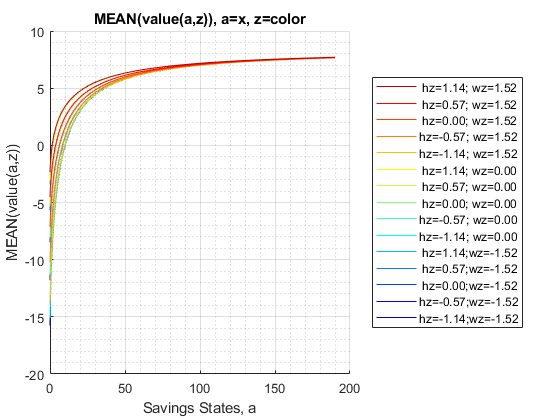

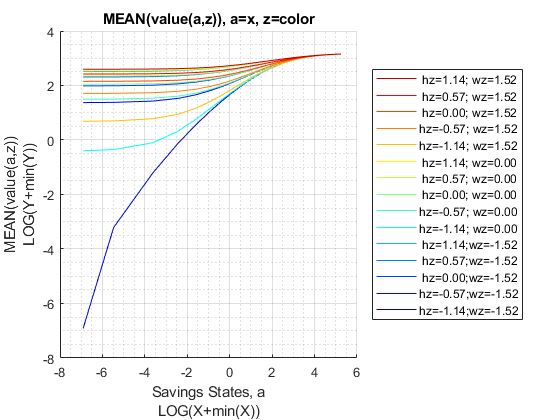

mp_support_graph('cl_st_graph_title') = {'MEAN(value(a,z)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(value(a,z))'};
ff_graph_grid((tb_az_v{1:end, 3:end})', ar_st_eta_HS_grid, agrid, mp_support_graph);

Graph Mean Savings Choices:

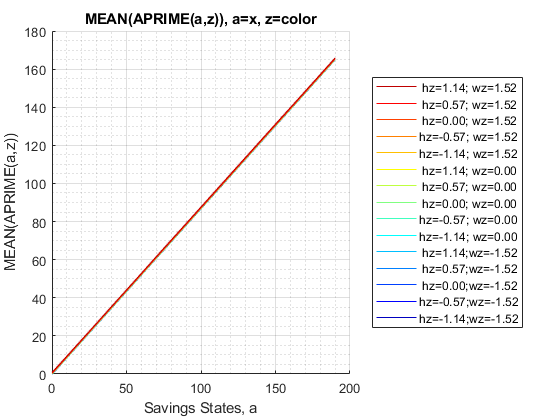

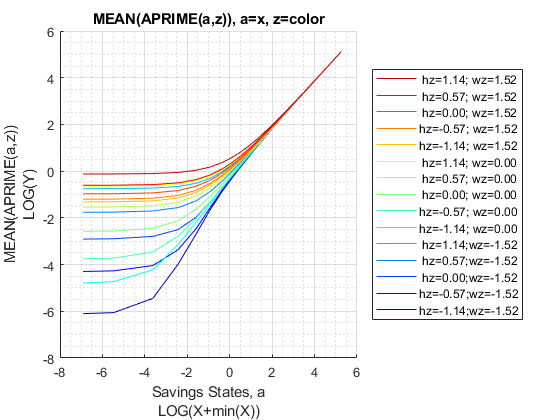

mp_support_graph('cl_st_graph_title') = {'MEAN(APRIME(a,z)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(APRIME(a,z))'};
ff_graph_grid((tb_az_ap{1:end, 3:end})', ar_st_eta_HS_grid, agrid, mp_support_graph);

Graph Mean Consumption:

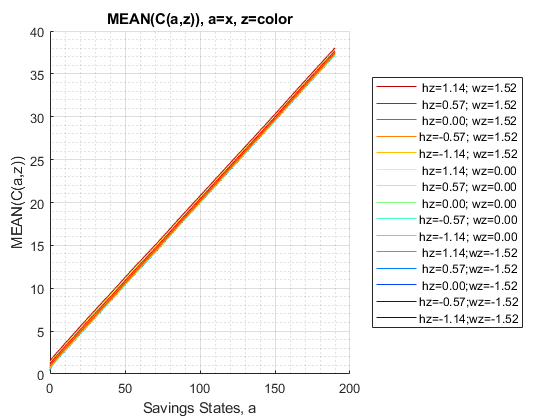

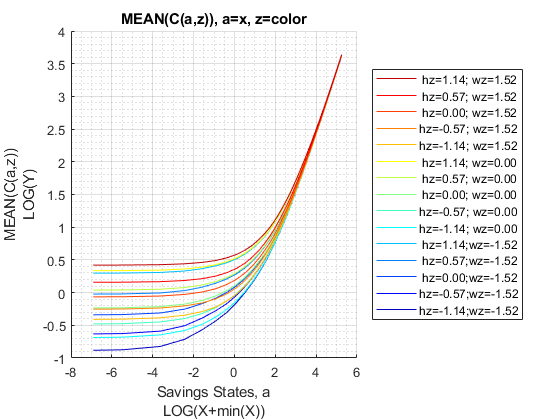

mp_support_graph('cl_st_graph_title') = {'MEAN(C(a,z)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(C(a,z))'};
ff_graph_grid((tb_az_c{1:end, 3:end})', ar_st_eta_HS_grid, agrid, mp_support_graph);

## Analyze Kids and Marriage and Age

Aggregating over education, savings, and shocks, what are the differential effects of Marriage and Age.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
ar_row_grid = [...
    "k0M0", "K1M0", "K2M0", "K3M0", "K4M0", ...
    "k0M1", "K1M1", "K2M1", "K3M1", "K4M1"];
mp_support_graph('cl_st_xtitle') = {'Age'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rounding') = '6.2f'; % format shock legend
mp_support_graph('cl_scatter_shapes') = {...
    'o', 'd' ,'s', 'x', '*', ...
    'o', 'd', 's', 'x', '*'};
mp_support_graph('cl_colors') = {...
    'red', 'red', 'red', 'red', 'red'...
    'blue', 'blue', 'blue', 'blue', 'blue'};

#### MEAN(VAL(KM,J)), MEAN(AP(KM,J)), MEAN(C(KM,J))

Tabulate value and policies:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,4,1,6,5];
% Value Function
tb_az_v = ff_summ_nd_array("MEAN(VAL(KM,J))", V_VFI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(VAL(KM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_19    mean_age_21    mean_age_23    mean_age_25    mean_age_27    mean_age_29    mean_age_31    mean_age_33    mean_age_35    mean_age_37    mean_age_39    mean_age_41    mean_age_43    mean_age_45    mean_age_47    mean_age_49    mean_age_51    mean_age_53    mean_age_55    mean_age_57    mean_age_59    mean_age_61    mean_age_63    mean_age_65    mean_age_67    mean_age_69    mean_age_71    

% Aprime Choice
tb_az_ap = ff_summ_nd_array("MEAN(AP(KM,J))", ap_VFI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(AP(KM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_19    mean_age_21    mean_age_23    mean_age_25    mean_age_27    mean_age_29    mean_age_31    mean_age_33    mean_age_35    mean_age_37    mean_age_39    mean_age_41    mean_age_43    mean_age_45    mean_age_47    mean_age_49    mean_age_51    mean_age_53    mean_age_55    mean_age_57    mean_age_59    mean_age_61    mean_age_63    mean_age_65    mean_age_67    mean_age_69    mean_age_71    

% Consumption Choices
tb_az_c = ff_summ_nd_array("MEAN(C(KM,J))", cons_VFI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(C(KM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_19    mean_age_21    mean_age_23    mean_age_25    mean_age_27    mean_age_29    mean_age_31    mean_age_33    mean_age_35    mean_age_37    mean_age_39    mean_age_41    mean_age_43    mean_age_45    mean_age_47    mean_age_49    mean_age_51    mean_age_53    mean_age_55    mean_age_57    mean_age_59    mean_age_61    mean_age_63    mean_age_65    mean_age_67    mean_age_69    mean_age_71    

Graph Mean Values:

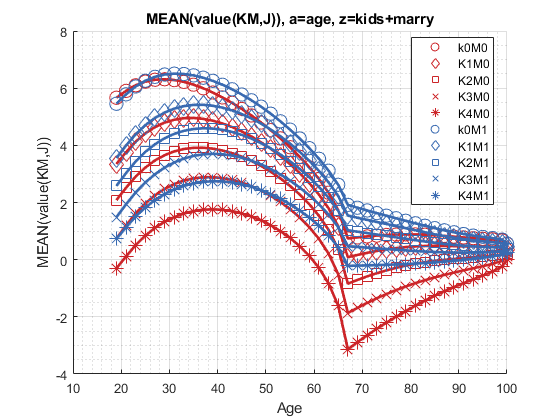

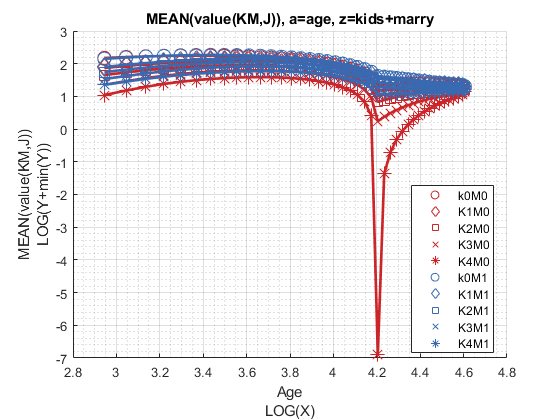

mp_support_graph('cl_st_graph_title') = {'MEAN(value(KM,J)), a=age, z=kids+marry'};
mp_support_graph('cl_st_ytitle') = {'MEAN(value(KM,J))'};
ff_graph_grid((tb_az_v{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Savings Choices:

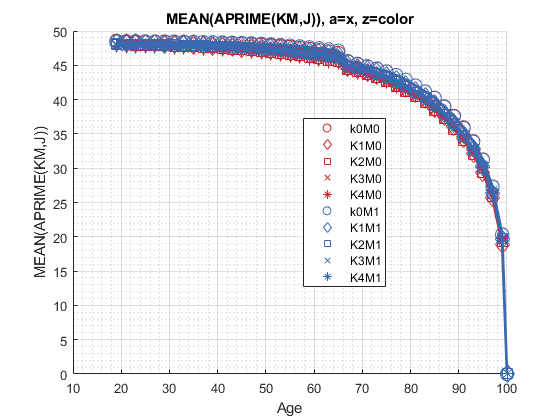

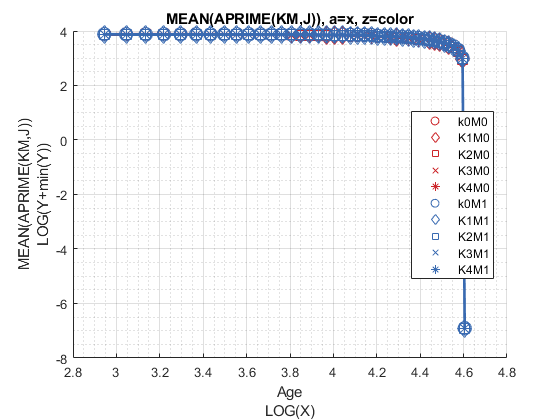

mp_support_graph('cl_st_graph_title') = {'MEAN(APRIME(KM,J)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(APRIME(KM,J))'};
ff_graph_grid((tb_az_ap{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Consumption:

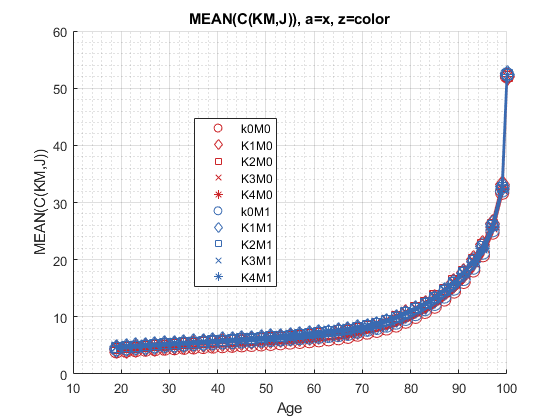

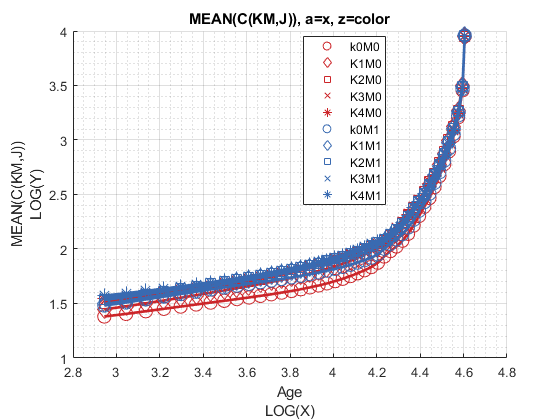

mp_support_graph('cl_st_graph_title') = {'MEAN(C(KM,J)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(C(KM,J))'};
ff_graph_grid((tb_az_c{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

## Analyze Education and Marriage and Age

Aggregating over education, savings, and shocks, what are the differential effects of Marriage and Age.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
ar_row_grid = ["E0M0", "E1M0", "E0M1", "E1M1"];
mp_support_graph('cl_st_xtitle') = {'Age'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rounding') = '6.2f'; % format shock legend
mp_support_graph('cl_scatter_shapes') = {'*', 'p', '*','p' };
mp_support_graph('cl_colors') = {'red', 'red', 'blue', 'blue'};

#### MEAN(VAL(EKM,J)), MEAN(AP(EKM,J)), MEAN(C(EKM,J))

Tabulate value and policies:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,6,1,4,5];
% Value Function
tb_az_v = ff_summ_nd_array("MEAN(VAL(EKM,J))", V_VFI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(VAL(EKM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_19    mean_age_21    mean_age_23    mean_age_25    mean_age_27    mean_age_29    mean_age_31    mean_age_33    mean_age_35    mean_age_37    mean_age_39    mean_age_41    mean_age_43    mean_age_45    mean_age_47    mean_age_49    mean_age_51    mean_age_53    mean_age_55    mean_age_57    mean_age_59    mean_age_61    mean_age_63    mean_age_65    mean_age_67    mean_age_69    mean_age_71    

% Aprime Choice
tb_az_ap = ff_summ_nd_array("MEAN(AP(EKM,J))", ap_VFI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(AP(EKM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_19    mean_age_21    mean_age_23    mean_age_25    mean_age_27    mean_age_29    mean_age_31    mean_age_33    mean_age_35    mean_age_37    mean_age_39    mean_age_41    mean_age_43    mean_age_45    mean_age_47    mean_age_49    mean_age_51    mean_age_53    mean_age_55    mean_age_57    mean_age_59    mean_age_61    mean_age_63    mean_age_65    mean_age_67    mean_age_69    mean_age_71    

% Consumption Choices
tb_az_c = ff_summ_nd_array("MEAN(C(EKM,J))", cons_VFI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(C(EKM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_19    mean_age_21    mean_age_23    mean_age_25    mean_age_27    mean_age_29    mean_age_31    mean_age_33    mean_age_35    mean_age_37    mean_age_39    mean_age_41    mean_age_43    mean_age_45    mean_age_47    mean_age_49    mean_age_51    mean_age_53    mean_age_55    mean_age_57    mean_age_59    mean_age_61    mean_age_63    mean_age_65    mean_age_67    mean_age_69    mean_age_71    

Graph Mean Values:

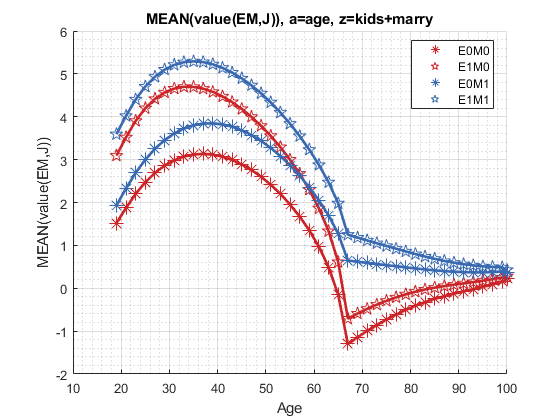

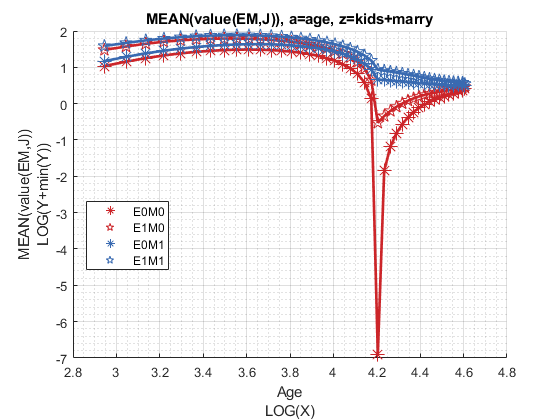

mp_support_graph('cl_st_graph_title') = {'MEAN(value(EM,J)), a=age, z=kids+marry'};
mp_support_graph('cl_st_ytitle') = {'MEAN(value(EM,J))'};
ff_graph_grid((tb_az_v{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Savings Choices:

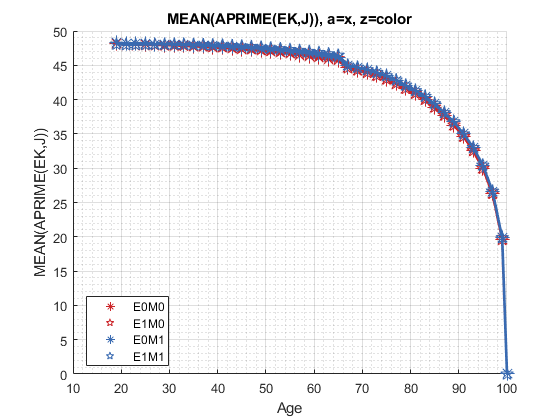

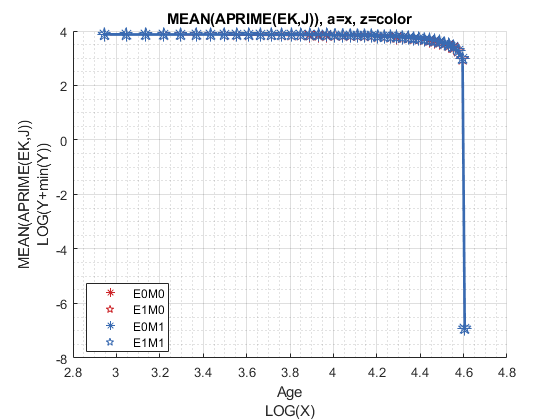

mp_support_graph('cl_st_graph_title') = {'MEAN(APRIME(EK,J)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(APRIME(EK,J))'};
ff_graph_grid((tb_az_ap{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Consumption:

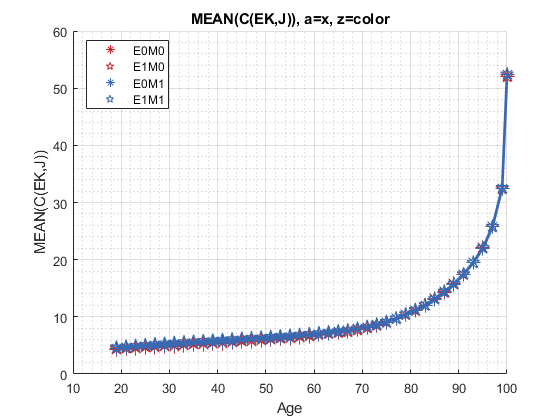

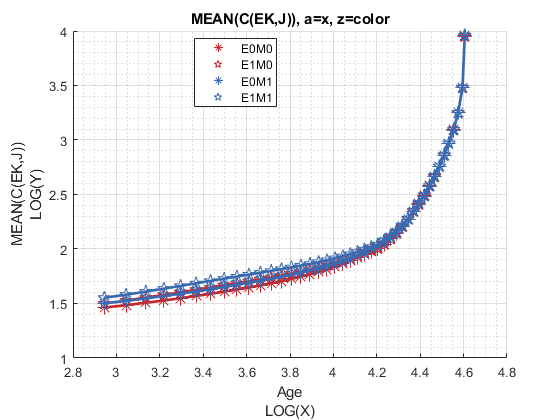

mp_support_graph('cl_st_graph_title') = {'MEAN(C(EK,J)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(C(EK,J))'};
ff_graph_grid((tb_az_c{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);